% Load the trained model
disp('Loading the trained model...');

Loading the trained model...


load('hand_gesture_model.mat', 'net');

% Initialize webcam or video reader
cam = webcam;  % For webcam feed
% videoReader = VideoReader('path_to_video_file.mp4');  % For video file input

% Create a figure for the webcam feed
figure('Name', 'Hand Gesture Recognition', 'NumberTitle', 'off');
h1 = axes;  % Create axes for displaying webcam frame

% Create a separate figure for the predictions
figure('Name', 'Predicted Gesture', 'NumberTitle', 'off');
h2 = axes;  % Create axes for displaying predicted gesture frame

% Start video recognition
disp('Starting video recognition... Press Ctrl+C to stop.');

Starting video recognition... Press Ctrl+C to stop.


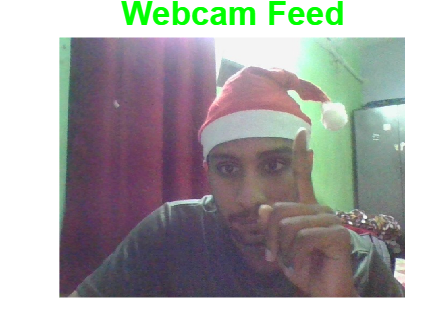

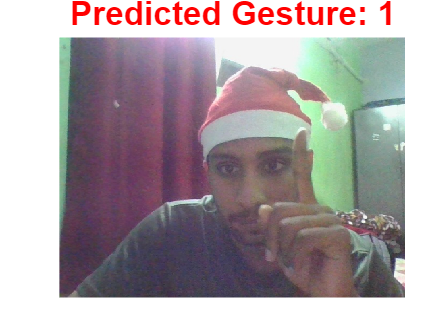

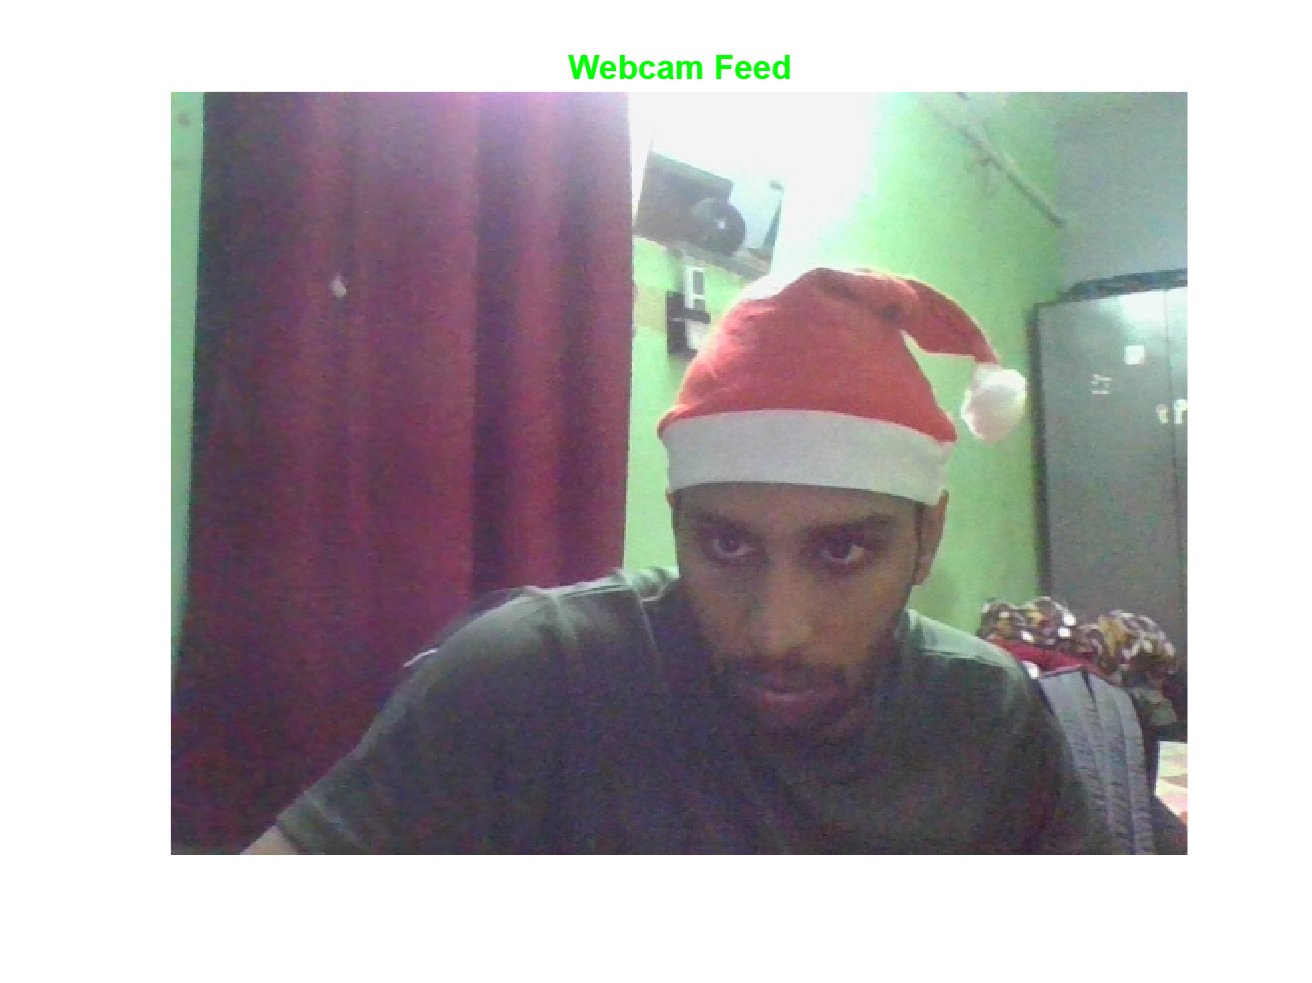

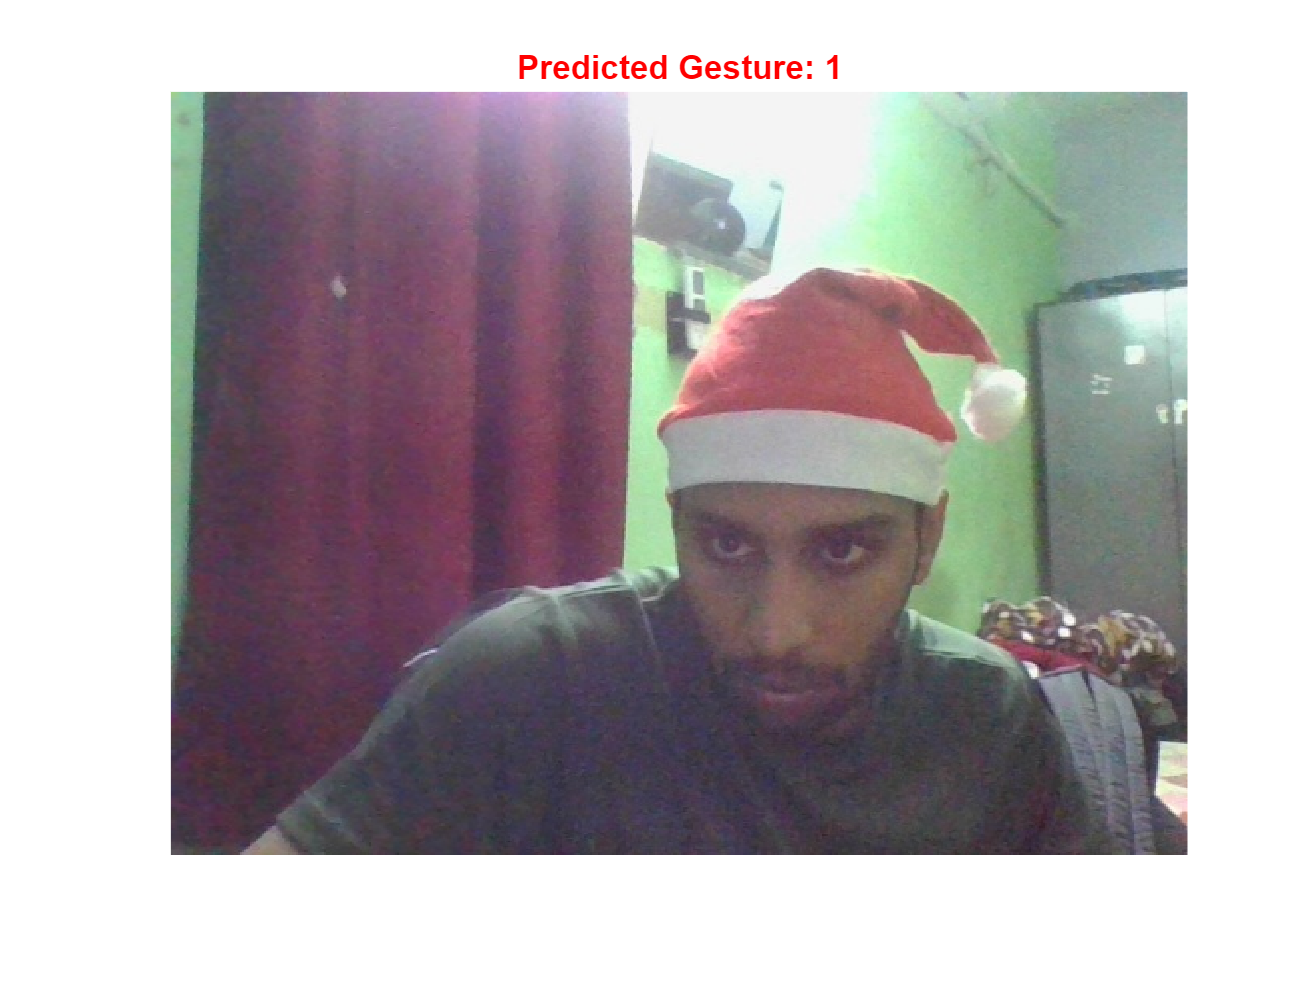


while true
    try
        % Capture a frame from the webcam
        frame = snapshot(cam);  % Use readFrame(videoReader) for video files

        % Preprocess the frame (resize, normalization, etc.)
        frameResized = imresize(frame, [64 64]);  % Resize to match model input size
        if size(frameResized, 3) == 1
            frameResized = cat(3, frameResized, frameResized, frameResized); % Convert grayscale to RGB
        end

        % Normalize the frame (if required)
        frameNormalized = double(frameResized) / 255;  % Scale pixel values to [0, 1]

        % Predict the gesture using the trained model
        predictedLabel = classify(net, frameNormalized);  % 'net' is your trained network

        % Display the webcam frame in the first figure
        imshow(frame, 'Parent', h1);
        title(h1, 'Webcam Feed', 'FontSize', 16, 'Color', 'g');
        
        % Display the prediction in the second figure (separate window)
        imshow(frame, 'Parent', h2);
        title(h2, ['Predicted Gesture: ', char(predictedLabel)], 'FontSize', 16, 'Color', 'r');

        % Pause to control frame rate (optional)
        pause(0.1);  % Adjust frame rate as needed
    catch ME
        disp('Error during video processing:');
        disp(ME.message);
        break;
    end
end


% Clean up
clear cam;
disp('Video recognition stopped.');

       